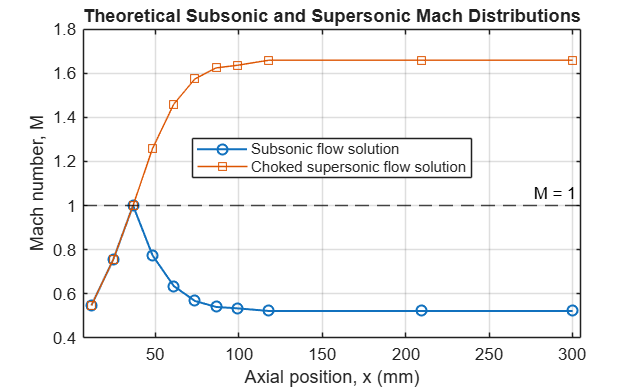

% Theoretical Mach Number and Static Pressure Distributions
%
% Assumptions:
% - Air with gamma = 1.4
% - Ideal, one-dimensional, isentropic flow
% - For the choked supersonic case: subsonic upstream, sonic at the throat,
%   supersonic downstream.
%
% The fully subsonic branch is plotted separately as an area-Mach
% reference. It is not the actual unchoked solution for the experimental
% subsonic operating condition.

% De Laval Nozzle specs, taken from lab report

tap = 1:11;

x = [11.6 24.7, 36.6, 48.3, 61.0, 73.7, 86.4, 99.1, 118.0, 209.5, 300.1];

areaRatio = [1.26 1.06, 1.00, 1.05, 1.15, 1.23, 1.27, 1.28, 1.30, 1.30, 1.30];

gamma = 1.4;

% Calculate subsonic and supersonic Mach solutions
M_sub = zeros(size(x));
M_sup = zeros(size(x));

for i = 1:length(x)

    AR = areaRatio(i);

    if abs(AR - 1) < 1e-10
        % Sonic condition at the throat
        M_sub(i) = 1;
        M_sup(i) = 1;
    else
        % Subsonic solution
        M_sub(i) = fzero(@(M) ...
            areaMachFunction(M, gamma) - AR, ...
            [1e-5, 0.999999]);

        % Supersonic solution
        M_sup(i) = fzero(@(M) ...
            areaMachFunction(M, gamma) - AR, ...
            [1.000001, 5]);
    end
end

% Define physically appropriate branches
% Upstream of throat: both branches are subsonic
% At throat: M = 1
% Downstream: branches diverge

throatIndex = find(abs(areaRatio - 1) < 1e-10, 1);

if isempty(throatIndex)
    error('No throat found where A/A* = 1.');
end

M_sub_branch = M_sub;
M_sup_branch = M_sub;

% Downstream of throat, retain subsonic solution
M_sub_branch(throatIndex+1:end) = ...
    M_sub(throatIndex+1:end);

% Downstream of throat, use supersonic solution
M_sup_branch(throatIndex+1:end) = ...
    M_sup(throatIndex+1:end);

% Calculate normalized isentropic static pressure ratios
% p/p0 = (1 + (gamma-1)/2 * M^2)^(-gamma/(gamma-1))

pRatio_sub_branch = ...
    (1 + (gamma-1)/2 .* M_sub_branch.^2) ...
    .^ (-gamma/(gamma-1));

pRatio_sup_branch = ...
    (1 + (gamma-1)/2 .* M_sup_branch.^2) ...
    .^ (-gamma/(gamma-1));


figure('Color','w');

plot(x, M_sub_branch, '-o', 'LineWidth', 1.2);
hold on;
plot(x, M_sup_branch, '-s');

yline(1, '--k', 'M = 1');

xlabel('Axial position, x (mm)');
ylabel('Mach number, M');
title('Theoretical Subsonic and Supersonic Mach Distributions');

grid on;
box on;
xlim([min(x)-5, max(x)+5]);

legend('Subsonic flow solution', ...
    'Choked supersonic flow solution', ...
    'Location','best');

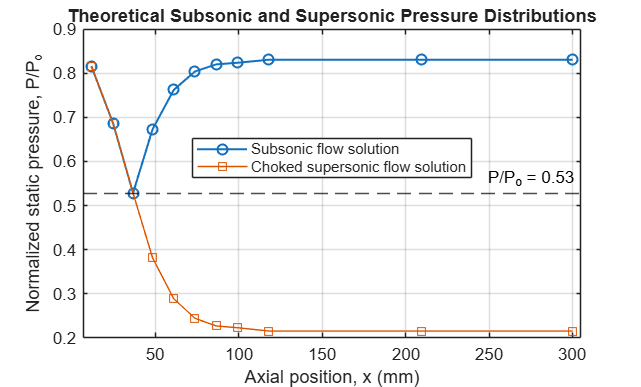



figure('Color','w');

plot(x, pRatio_sub_branch, '-o', 'LineWidth', 1.2);
hold on;
plot(x, pRatio_sup_branch, '-s');

yline(0.52828, '--k', 'P/P_o = 0.53');

xlabel('Axial position, x (mm)');
ylabel('Normalized static pressure, P/P_o');
title('Theoretical Subsonic and Supersonic Pressure Distributions');

grid on;
box on;
xlim([min(x)-5, max(x)+5]);

legend('Subsonic flow solution', ...
    'Choked supersonic flow solution', ...
    'Location','best');


results = table(tap', x', areaRatio', ...
    M_sub_branch', M_sup_branch', ...
    pRatio_sub_branch', pRatio_sup_branch', ...
    'VariableNames', {'Tap','x_mm','AreaRatio', ...
    'M_subsonic_branch','M_supersonic_branch', ...
    'p_p0_subsonic_branch','p_p0_supersonic_branch'});

disp(results);

    Tap    x_mm     AreaRatio    M_subsonic_branch    M_supersonic_branch    p_p0_subsonic_branch    p_p0_supersonic_branch
    ___    _____    _________    _________________    ___________________    ____________________    ______________________

     1      11.6      1.26            0.54666               0.54666                0.81614                  0.81614        
     2      24.7      1.06            0.75439               0.75439                0.68572                  0.68572        
     3      36.6         1                  1                     1                0.52828                  0.52828        
     4      48.3      1.05            0.77383                1.2589                0.67307                  0.38149        
     5        61 

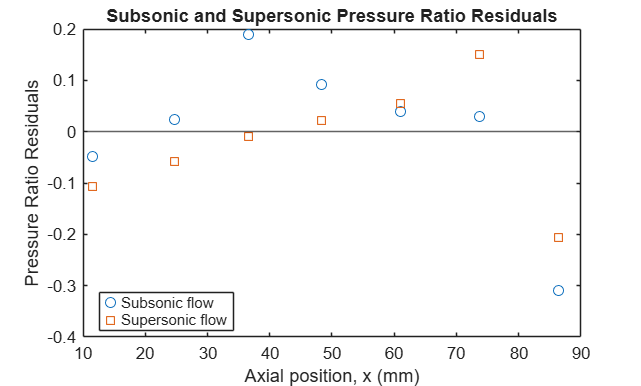


% Area-Mach relation
function AR = areaMachFunction(M, gamma)

AR = (1 ./ M) .* ((2/(gamma+1)) .* ...
    (1 + ((gamma-1)/2).*M.^2)) .^ ((gamma+1)/(2*(gamma-1)));

end

% Error and residuals

exp_pressure_sub = [0.7671 0.7085 0.7179 0.7640 0.8023 0.8327 0.5100];
error_pressure = abs(exp_pressure_sub - pRatio_sub_branch(1:7)) * 100 ./ pRatio_sub_branch(1:7);

exp_pressure_sup = [0.7094 0.6284 0.5189 0.4032 0.3442 0.3941 0.0214];

figure;
plot(x(1:7), exp_pressure_sub - pRatio_sub_branch(1:7), 'o');
hold on;
plot(x(1:7), exp_pressure_sup - pRatio_sup_branch(1:7), 's');
yline(0, '-')
xlabel('Axial position, x (mm)');
ylabel('Pressure Ratio Residuals');
title('Subsonic and Supersonic Pressure Ratio Residuals');
legend('Subsonic flow', 'Supersonic flow', 'Location','best');

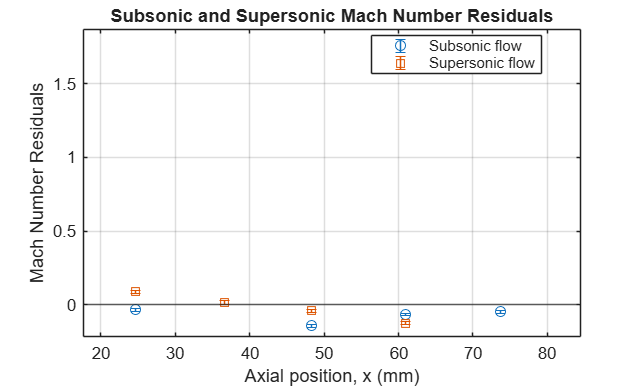


exp_mach_sub = [0.6273    0.7193    0.7047    0.6323    0.5699    0.5182    1.0299];
exp_mach_sup = [0.7178    0.8424    1.0152    1.2171    1.3346    1.2345    3.1607];

machResidualSub = exp_mach_sub - M_sub_branch(1:7);
machResidualSup = exp_mach_sup - M_sup_branch(1:7);
mach_sub_err = [0.0097    0.0117    0.0145    0.0098    0.0085    0.0076    0.0213];
mach_sup_err = [0.0116    0.0149    0.0208    0.0323    0.0407    0.0343    0.4363];

figure;
errorbar(x(1:7), machResidualSub, mach_sub_err, 'o');
hold on;
errorbar(x(1:7), machResidualSup, mach_sub_err, 's');
yline(0, '-');
xlabel('Axial position, x (mm)');
ylabel('Mach Number Residuals');
title('Subsonic and Supersonic Mach Number Residuals');
legend('Subsonic flow', 'Supersonic flow', 'Location','best');
grid on;